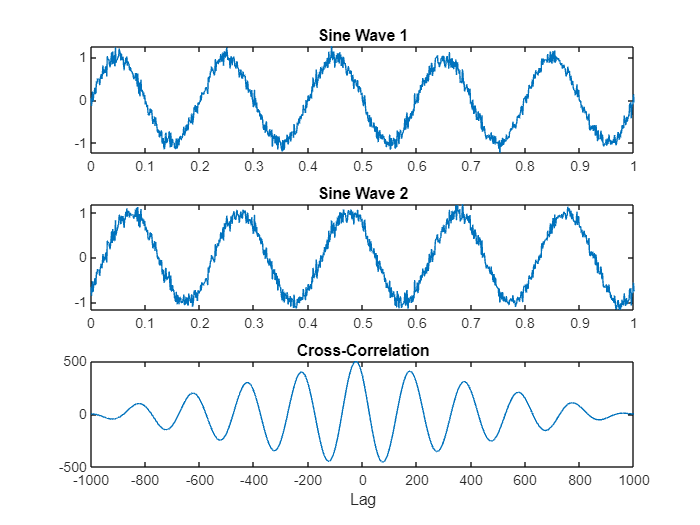

% Generate two sine waves with noise
fs = 1000; % Sampling frequency
t = 0:1/fs:1; % Time vector from 0 to 1 second
f1 = 5; % Frequency of the first sine wave
f2 = 5; % Frequency of the second sine wave
A = 1; % Amplitude

% Create two sine waves with a phase shift
sine_wave_1 = A * sin(2*pi*f1*t);
sine_wave_2 = A * sin(2*pi*f2*t - pi/4); % Adding a phase shift of pi/4

% Add some noise
noise = 0.1 * randn(size(t));
sine_wave_1 = sine_wave_1 + noise;
sine_wave_2 = sine_wave_2 + noise;

% Calculate cross-correlation
cross_corr = xcorr(sine_wave_1, sine_wave_2);

% Plot the original sine waves
figure;
subplot(3,1,1);
plot(t, sine_wave_1);
title('Sine Wave 1');
subplot(3,1,2);
plot(t, sine_wave_2);
title('Sine Wave 2');

% Plot the cross-correlation
lag = -(length(t)-1):(length(t)-1);
subplot(3,1,3);
plot(lag, cross_corr);
title('Cross-Correlation');
xlabel('Lag');


% Find the lag at which cross-correlation is maximum
[~, idx_max] = max(cross_corr);
lag_max = lag(idx_max);

disp(['The lag at which cross-correlation is maximum: ' num2str(lag_max)]);

The lag at which cross-correlation is maximum: -26


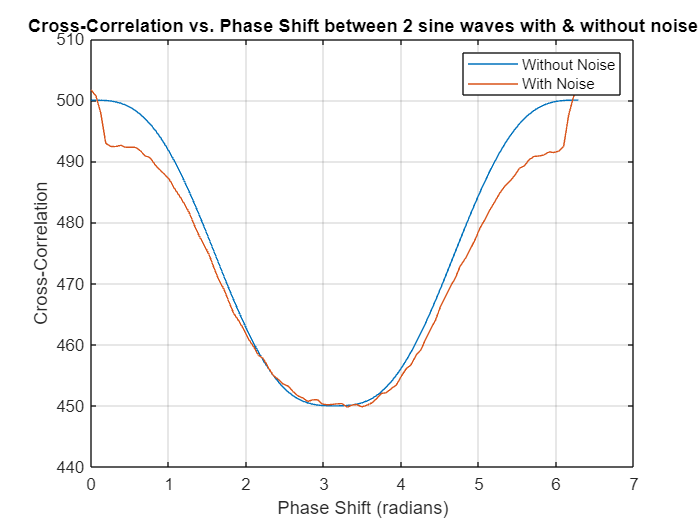





% Generate two sine waves with noise
fs = 1000; % Sampling frequency
t = 0:1/fs:1; % Time vector from 0 to 1 second
f1 = 5; % Frequency of the first sine wave
f2 = 5; % Frequency of the second sine wave
A1 = 1; % Amplitude
A2 = 2;
% Create two sine waves without a phase shift
sine_wave_1 = A1 * sin(2*pi*f1*t);
sine_wave_2 = A2 * sin(2*pi*f2*t); 

% Add some noise
noise = 0.1 * randn(size(t));
sine_wave_3 = sine_wave_1 + noise;
sine_wave_4 = sine_wave_2 + noise;

% Range of phase shifts to explore
phase_shifts = linspace(0, 2*pi, 100);

% Initialize array to store cross-correlation results
cross_corr_results = zeros(size(phase_shifts));

% Loop through different phase shifts
for i = 1:length(phase_shifts)
    % Apply the current phase shift to sine_wave_2
    sine_wave_2_shifted = A * sin(2*pi*f2*t - phase_shifts(i)) ;
    
    % Calculate cross-correlation
    cross_corr = xcorr(sine_wave_1, sine_wave_2_shifted);
    
    % Store the maximum cross-correlation value
    cross_corr_results(i) = max(cross_corr);
end

for i = 1:length(phase_shifts)
    % Apply the current phase shift to sine_wave_4
    sine_wave_4_shifted = A * sin(2*pi*f2*t - phase_shifts(i)) + noise;
    
    % Calculate cross-correlation
    cross_corr_1 = xcorr(sine_wave_3, sine_wave_4_shifted);
    
    % Store the maximum cross-correlation value
    cross_corr_results_1(i) = max(cross_corr_1);
end

% Plot the results
figure;
plot(phase_shifts, cross_corr_results);
hold on;
plot(phase_shifts,cross_corr_results_1)
grid on;
title('Cross-Correlation vs. Phase Shift between 2 sine waves with & without noise');
xlabel('Phase Shift (radians)');
ylabel('Cross-Correlation');

legend(["Without Noise","With Noise"])

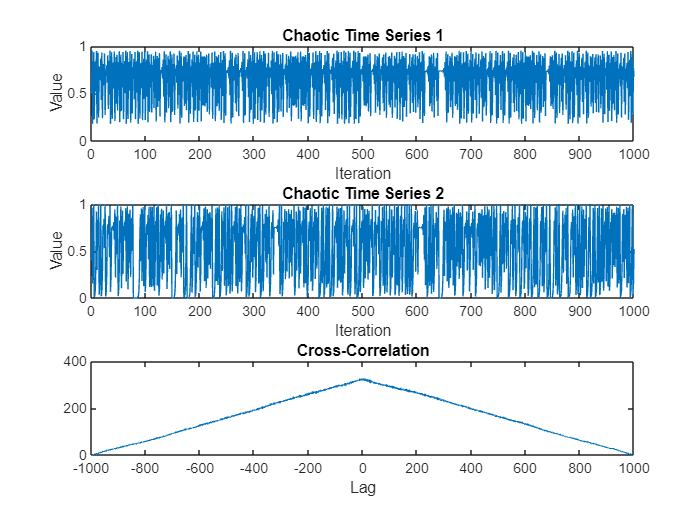




% Parameters for chaotic time series 1
r1 = 3.8; % Control parameter for series 1
nIterations = 1000; % Number of iterations
initialCondition1 = 0.5; % Initial condition for series 1

% Parameters for chaotic time series 2
r2 = 4; % Control parameter for series 2
initialCondition2 = 0.4; % Initial condition for series 2

% Initialize the time series arrays
chaoticSeries1 = zeros(1, nIterations);
chaoticSeries2 = zeros(1, nIterations);

% Generate chaotic time series using the logistic map
chaoticSeries1(1) = initialCondition1;
chaoticSeries2(1) = initialCondition2;

for n = 2:nIterations
    chaoticSeries1(n) = r1 * chaoticSeries1(n-1) * (1 - chaoticSeries1(n-1));
    chaoticSeries2(n) = r2 * chaoticSeries2(n-1) * (1 - chaoticSeries2(n-1));
end

% Calculate cross-correlation
cross_corr = xcorr(chaoticSeries1, chaoticSeries2);

% Plot the chaotic time series
figure;
subplot(3,1,1);
plot(1:nIterations, chaoticSeries1);
title('Chaotic Time Series 1');
xlabel('Iteration');
ylabel('Value');

subplot(3,1,2);
plot(1:nIterations, chaoticSeries2);
title('Chaotic Time Series 2');
xlabel('Iteration');
ylabel('Value');

% Plot the cross-correlation
lag = -(nIterations-1):(nIterations-1);
subplot(3,1,3);
plot(lag, cross_corr);
title('Cross-Correlation');
xlabel('Lag');


% Find the lag at which cross-correlation is maximum
[~, idx_max] = max(cross_corr);
lag_max = lag(idx_max);

disp(['The lag at which cross-correlation is maximum: ' num2str(lag_max)]);

The lag at which cross-correlation is maximum: 2


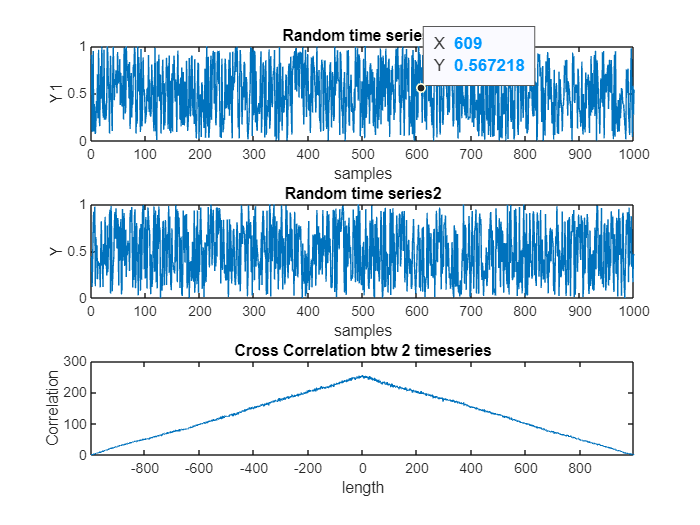



%to generate time series using a random time series:
nSamples = 1000;

random_ts1 = rand(1,nSamples);
random_ts2 = rand(1,nSamples);

cross_corr_random = xcorr(random_ts1,random_ts2);
figure;
subplot(3,1,1);
plot(1:nSamples,random_ts1);
subplot(3,1,2);
plot(1:nSamples, random_ts2);
lag = -(length(random_ts1)-1):(length(random_ts1) - 1);
subplot(3,1,3);
plot(lag,cross_corr_random);

subplot(3,1,2)
xlim([0 1000])
ylim([0.00 1.00])
subplot(3,1,3)
title("Cross Correlation btw 2 timeseries")
xlabel("length")
ylabel("Correlation")
subplot(3,1,1)
title("Random time series 1")
xlabel("samples")
ylabel("Y1")
 
ax = gca;
chart = ax.Children(1);
datatip(chart,610,0.4546);
subplot(3,1,2)
xlim([0 1000])
ylim([0.00 1.00])
title("Random time series2")
xlabel("samples")
ylabel("Y")
subplot(3,1,3)
xlim([-998 998])
ylim([0 300])
title("Cross Correlation btw 2 timeseries")
xlabel("length")
ylabel("Correlation")